# **Matlab homework (lab 2)**

 clear; close all;
% insert your names and IDs here
Name{1} = 'David Pérez Carrasco';
NIA{1} = 241375;
Name{2} = 'Guillem Escriba Molto';
NIA{2} = 242123;

% ALSO : Do not use make additional calls to "clear all;" between steps.

%% load file from .mat 
load dataset.mat % you can edit here if your datafile has a different name (datafile.mat), but do not add path to the file (otherwise it does not work on a different computer)

# QUESTION 2

% Enter code for question 2 here
%file matrix = M

n = size(M,1); % número de muestras.
k = size(M,2)-1; % número de regresores.

X = M; % matriz cargada

X(:,k+1) = []; % borramos la última columna de la matriz, y.
y = M(:,3); % extraemos los valores de y.
%mdl = fitlm(X,y) %Con esta línea de código podemos comprovar los valores 

mdl = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate         SE         tStat       pValue   
                   _________    __________    _______    ___________

    (Intercept)       39.123        1.2995     30.106    5.2496e-106
    x1             -0.005578    0.00047276    -11.799     7.1692e-28
    x2                1.1976       0.20257     5.9121     7.1055e-09


Number of observations: 414, Error degrees of freedom: 411
Root Mean Squared Error: 9.68
R-squared: 0.497,  Adjusted R-Squared: 0.494
F-statistic vs. constant model: 203, p-value = 5.61e-62

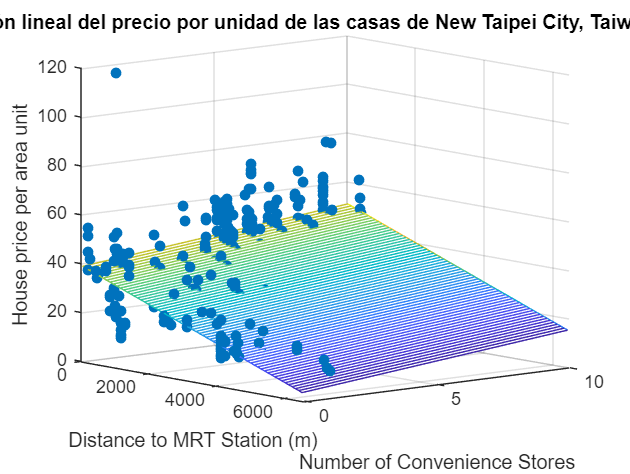

aux = ones(n,1); % primera columna de X.
X = [aux X]; % concatenamos ambas matrices obteniendo así X.
x1 = M(:,1); % extraemos los valores del primer regresor.
x2 = M(:,2); % extraemos los valores del segundo regresor.
y_mean = mean(y); % calculamos la media de y.

Xt = transpose(X); % hacemos la transpuesta de X.
XtX = Xt*X; % multiplicamos la transpuesta de X por X.
XtY = Xt*y; % multiplicamos la transpuesta de X por y. 
XtX1 = inv(XtX); % calculamos la inversa de XtX.
b = XtX1*XtY; % obtenemos los valores de b con el método de mínimos cuadrados.
y_aprox = X*b; % multiplicamos los valores de X por los coeficientes b.


scatter3(x1,x2,y,'filled')  %dibujamos todos los puntos en 3D
hold on
x1fit = min(x1):100:max(x1); %acotamos los valores de x1 y x2
x2fit = min(x2):10:max(x2); 
[X1FIT,X2FIT] = meshgrid(x1fit,x2fit);  %dibujamos la cuadrícula
YFIT = b(1) + b(2)*X1FIT + b(3)*X2FIT; %recta de regresión lineal
mesh(X1FIT,X2FIT,YFIT) %dibujamos la mesh
title('Regresión lineal del precio por unidad de las casas de New Taipei City, Taiwan en 2013');
xlabel('Distance to MRT Station (m)')
ylabel('Number of Convenience Stores')
zlabel('House price per area unit')
view(50,10)
hold off

Como podemos ver, de esta regresión lineal obtenemos un plano bastante correlacionado, donde se observa la relación entre el precio por unidad de las casas con su distancia al servicio de transporte público y también con el número de tiendas de conveniencia ('supers'). En primer lugar, la forma del primer predictor, la distancia a la estación de metro más cercana es claramente decreciente respecto al precio por unidad, de modo que cuanto más cercana sea la casa a la estación de metro generalmente supone un mayor precio para el hogar, lo cual demuestra que la conveniencia del transporte público realmente tiene una incidencia a la hora de escoger un hogar, o al menos en esta ciudad. El segundo regresor, el número de tiendas de conveniencia, tiene una forma peculiar debido a que sus variables son valores discretos, por lo que se aprecia la distinción entre columnas, quizá menos atractivo pero no menos eficaz, ya que nos permite ver la clara correlación entre el número de tiendas cercanas y el precio de la casa, ya que cuantas más tiendas hay cercanas mayor es el precio, seguramente debido a que esto implica una posición más céntrica y práctica del hogar, con muchas facilidades al alcance, y como vemos también tiene una incidencia importante. En conclusión podemos ver como las casas son más valoradas cuanto más prácticas sea, siendo las más céntricas, o al menos las que se encuentran alrededor de más tiendas y cercanas al transporte público las más caras.

# QUESTION 3

% write your code here code

v = n-k-1; %grados de libertad total

SS_REG = sum(power(y_aprox-y_mean,2)); % suma cuadrados modelo
SS_ERR = sum(power(y-y_aprox,2)); % suma cuadrados error
SS_TOT = SS_REG + SS_ERR; % suma cudrados total

MS_REG = SS_REG/k; % suma cuadrados modelo media
MS_ERR = SS_ERR/(n-k-1); % suma cuadrados error media

R2 = SS_REG/SS_TOT % Coeficiente de determinación

R2 = 0.4966



F = MS_REG/MS_ERR; % F value
f = finv(0.975,k,v); %calculamos la t para alpha=0.05, k=2 y v grados de libertad

fprintf('Confidence Interval of test F: [%8.4f,%8.4f]',0,f);

Confidence Interval of test F: [  0.0000,  3.7222]

fprintf('Value of F: %8.4f',F);

Value of F: 202.6984


p_f = 1-fcdf(F,k,v); %Valor p del test F
fprintf('Value of p: %8.4f',p_f);

Value of p:   0.0000

El coeficiente de determinación obtenido es del 49,66%, lo cual nos indica que el modelo linear representa una gran parte de la variabilidad de los datos, puesto que hablamos de casi un 50% de proporción de variación de la variable dependiente respecto a las independientes, lo cual ciertamente indica una importante proporción, pero también es cierto que el valor no es tan elevado como para afirmar que nuestro modelo encaja perfectamente con los datos. El número de variables (si obtuviéramos varios miles sería un estudio más exacto) ha podido producir que la variación de ciertos datos tenga más relevancia en la muestra de la que tendría si hubiera miles de datos siguiendo un patrón, causando que la proporción de variación no sea tan elevada como podríamos esperar. De todas formas, con un valor de un 50% podríamos considerar que el modelo es aceptable, pero que ciertamente no explica del todo el comportamiento de todos los datos, lo cual podría incrementarse al añadir muchos más datos, en caso de que estos siguieran el mismo patrón ya que los datos menos proporcionales acabarían teniendo un menor peso. Además, también podría deberse a que una de las variables es discreta, puesto que esto provoca un comportamiento extraño en esa dirección, al crear la formación de columnas como hemos podido ver, eso hace que sea más difícil para el modelo predecir el comportamiento en ambas direcciones, puesto que se trata de un modelo contínuo y el tener tantos datos discretos tan diferenciados puede provocar una representación menos adecuada.

También podemos observar como el valor de F es muy elevado, y el intervalo que obtenemos con el test F va hasta un valor muy pequeño, por lo que rechazamos claramente la hipótesis nula de que todos los coeficientes incluyen el 0 y por tanto concluímos que los coeficientes regresivos son significativos y obtendremos un modelo válido. Finalmente, observamos también que el valor p es muy pequeño, prácticamente negligible, por lo que podríamos rechazar el test simplemente al obtener el valor p.

# QUESTION 4

% write your code here
s2 = MS_ERR; % variancia mostral
VAR = s2*XtX1; % variancia 

t0 = b(1)/sqrt(VAR(1,1)); % t value b0
t1 = b(2)/sqrt(VAR(2,2)); % t value b1
t2 = b(3)/sqrt(VAR(3,3)); % t value b2

t = tinv(0.975,v); %calculamos la t para alpha=0.05 y v grados de libertad
fprintf('Confidence Interval of test t: [%8.4f,%8.4f]',-t,t);

Confidence Interval of test t: [ -1.9658,  1.9658]

fprintf('Value of t0: %8.4f',t0);

Value of t0:  30.1060

fprintf('Value of t1: %8.4f',t1);

Value of t1: -11.7989

fprintf('Value of t2: %8.4f',t2);

Value of t2:   5.9121


p0 = 2*(1-tcdf(abs(t0),v)); % Compute p value for t0
p1 = 2*(1-tcdf(abs(t1),v)); % Compute p value for t0
p2 = 2*(1-tcdf(abs(t2),v)); % Compute p value for t0
fprintf('Value of p0: %8.4f',p0);

Value of p0:   0.0000

fprintf('Value of p1: %8.4f',p1);

Value of p1:   0.0000

fprintf('Value of p2: %8.4f',p2);

Value of p2:   0.0000

Como podemos ver, el intervalo de confianza para un alpha de 0.05 lo obtenemos entre -1.9658 y 1.9658, y por tanto todos los valores t obtenidos, tanto t0, como t1 como t2, se encuentran fuera del intervalo, y teniendo en cuenta que este intervalo de confianza representa la hipótesis de 0 pertenece al  inervalo de ninguno de los b, podemos rechazar dicha hipótesis nula y por tanto concluir que se trata de unos coeficientes de regresión significativos, tanto b0 como b1 como b2, y que por tanto el modelo de representación que obtendremos es válido. 

Ademñas, también observamos que los valores de p para los 3 coeficientes son muy pequños, prácticamente 0, por lo que immediatamenre rechazaríamos la hipótesis nula de cada uno y concluiríamos que son coeficientes singificativos.